clc
clear
RGB = readmatrix('thickness_all\thickness2rgb.csv');
t = RGB(:,1);
rgb_v = RGB(:,2:4)/256;
xyz_v = rgb2xyz(rgb_v);

x = 1000;       %薄膜厚度/nm
n = 1.428;      %薄膜折射率
n0 = 1;         %空气折射率
ng = 3.836;     %硅片折射率
i = 0;          %折射角
lambda = 360:830;
x = 1:x;
delta = 4*pi*n*x'*cos(i)./lambda;
R = (n^2*(n0-ng)^2*cos(delta/2).^2+(n^2-n0*ng)^2*sin(delta/2).^2)./...
       (n^2*(n0+ng)^2*cos(delta/2).^2+(n^2+n0*ng)^2*sin(delta/2).^2);
cie = colorMatchFcn('1931_full');
XYZ = R*cie(:,2:4);
xyz_norm = normalize(XYZ,2,'norm',1);
rgb = xyz2rgb(xyz_norm);

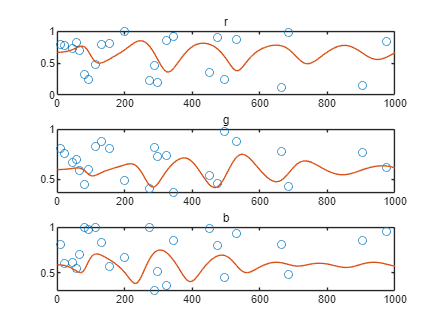

subplot(3,1,1)
plot(t,rgb_v(:,1),'o')
title('r')
hold on
plot(rgb(:,1))
hold off
subplot(3,1,2)
plot(t,rgb_v(:,2),'o')
title('g')
hold on
plot(rgb(:,2))
hold off
subplot(3,1,3)
plot(t,rgb_v(:,3),'o')
title('b')
hold on
plot(rgb(:,3))
hold off

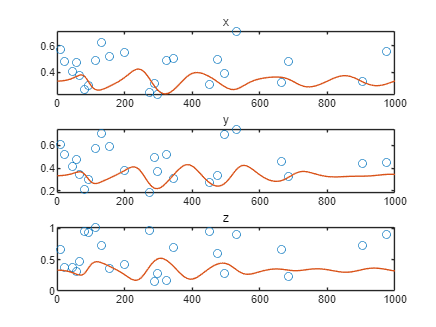

subplot(3,1,1)
plot(t,xyz_v(:,1),'o')
title('x')
hold on
plot(xyz_norm(:,1))
hold off
subplot(3,1,2)
plot(t,xyz_v(:,2),'o')
title('y')
hold on
plot(xyz_norm(:,2))
hold off
subplot(3,1,3)
plot(t,xyz_v(:,3),'o')
title('z')
hold on
plot(xyz_norm(:,3))
hold off

f = @(x)res(x, cie, R, t, xyz_v);
x0 = [10 10 10];   %初始值
figure
% options = optimoptions(@fmincon,'Algorithm','sqp','Display','iter',...
%     'PlotFcn',@optimplotfval,'MaxIterations',1000)
% [x,fval] = fmincon(f,x0,[],[],[],[],[0 0 0],[100 100 100],[],options)
problem = createOptimProblem('fmincon','objective',f,'x0',x0,...
    'lb',[0,0,0],'ub',[100,100,100]);
rng default
gs = GlobalSearch;
ms = MultiStart

ms =   MultiStart - 属性:

          UseParallel: 0
              Display: 'final'
    FunctionTolerance: 1.0000e-06
              MaxTime: Inf
            OutputFcn: []
              PlotFcn: []
     StartPointsToRun: 'all'
           XTolerance: 1.0000e-06


[x,fval] = run(ms,problem,50)


MultiStart completed the runs from all start points. 

All 50 local solver runs converged with a positive local solver exitflag.


x =     0.0202    0.0000    0.0000


fval = 4.6963

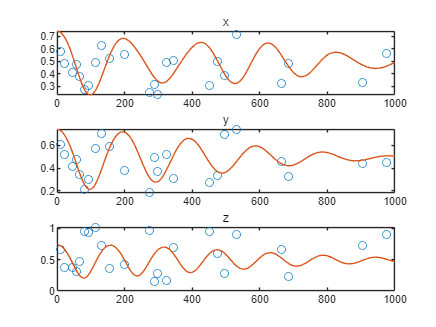

xyz_t = model(x, cie, R);
figure
subplot(3,1,1)
plot(t,xyz_v(:,1),'o')
title('x')
hold on
plot(xyz_t(:,1))
hold off
subplot(3,1,2)
plot(t,xyz_v(:,2),'o')
title('y')
hold on
plot(xyz_t(:,2))
hold off
subplot(3,1,3)
plot(t,xyz_v(:,3),'o')
title('z')
hold on
plot(xyz_t(:,3))
hold off

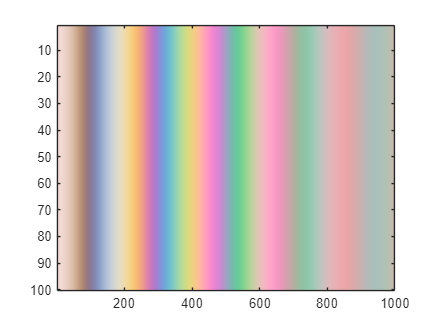

rgb_t = xyz2rgb(xyz_t);
rgb_t(:,1) = 0.85 * rgb_t(:,1);    % 手动修正系数
C2 = pagemtimes(reshape(rgb_t,[],1,3),ones(1,100,3));
figure
image(imrotate(C2,90))

rgbmatrix = 256 * rgb_t';
% save('rm_f.mat',"rgbmatrix")

function r = res(x, cie, R, t, xyz_v)
    X_t = R.*(x(1)+x(2)*cie(:,2)+x(3)*cie(:,2).^2)'*cie(:,2);
    Y_t = R.*(x(1)+x(2)*cie(:,3)+x(3)*cie(:,3).^2)'*cie(:,3);
    Z_t = R.*(x(1)+x(2)*cie(:,4)+x(3)*cie(:,4).^2)'*cie(:,4);
    xyz_t = [X_t, Y_t, Z_t];
    diff = (xyz_t(t)-xyz_v).^2;
    r = sum(diff,"all");
end
function xyz = model(x, cie, R)
    X_t = R.*(x(1)+x(2)*cie(:,2)+x(3)*cie(:,2).^2)'*cie(:,2);
    Y_t = R.*(x(1)+x(2)*cie(:,3)+x(3)*cie(:,3).^2)'*cie(:,3);
    Z_t = R.*(x(1)+x(2)*cie(:,4)+x(3)*cie(:,4).^2)'*cie(:,4);
    xyz = [X_t, Y_t, Z_t];
end